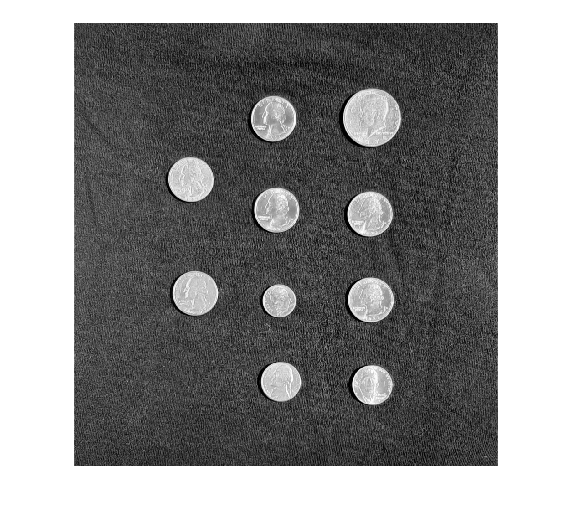

coinImage = imread("coinImage.png"); 
imshow(coinImage)

coinMask = imbinarize(coinImage);
coinMask = bwareaopen(coinMask,50)

coinMask = 972×930 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

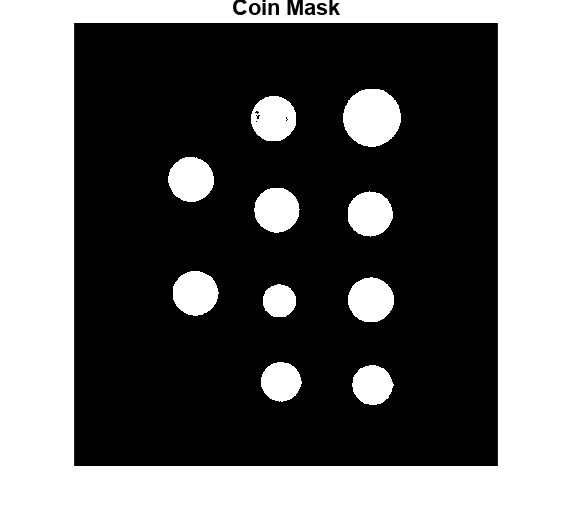

% Depending on the image, you might need to invert the mask. 
% If coins are black and background is white, then use:
% coinMask = ~coinMask;
maskedCoinImage = coinImage;
maskedCoinImage(repmat(~coinMask,[1 1 1])) = 0;
coinSizes = regionprops('table', coinMask, 'Area', 'Perimeter');
figure, imshow(coinMask), title('Coin Mask');

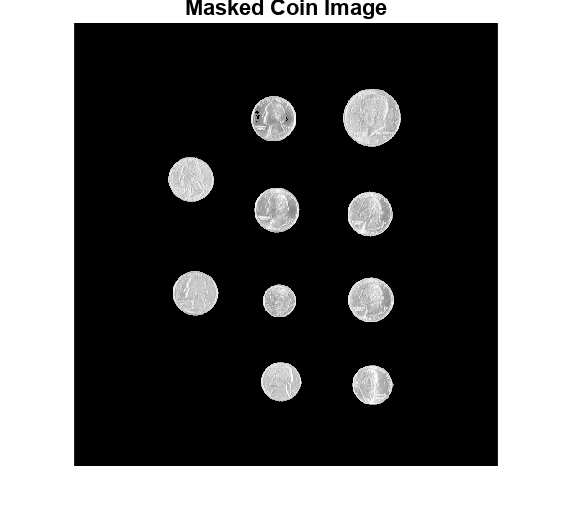

figure, imshow(maskedCoinImage), title('Masked Coin Image');

disp(coinSizes);

    Area     Perimeter
    _____    _________

     7700     310.03  
     7680     308.67  
     7677     311.92  
     7693     309.42  
     6019     274.98  
     4186     226.73  
    12708     397.88  
     7713     310.16  
     7780     312.17  
     6088     275.82  



% Area thresholds for classifying coins. add depednding on your coins
dimeThreshold = 5000;
nickelThreshold = 7000;
quarterThreshold = 8000;
% Grouping coins based on their areas
nDimes = sum(coinSizes.Area < dimeThreshold);
nNickels = sum(coinSizes.Area >= dimeThreshold & coinSizes.Area < nickelThreshold);
nQuarters = sum(coinSizes.Area >= nickelThreshold & coinSizes.Area < quarterThreshold);
nFiftyCents = sum(coinSizes.Area >= quarterThreshold);
% Calculating the total value
USD = nDimes * 0.10 + nNickels * 0.05 + nQuarters * 0.25 + nFiftyCents * 0.50;
% Display the results
fprintf('Number of Dimes: %d\n', nDimes);

Number of Dimes: 1


fprintf('Number of Nickels: %d\n', nNickels);

Number of Nickels: 2


fprintf('Number of Quarters: %d\n', nQuarters);

Number of Quarters: 6


fprintf('Number of Fifty Cents: %d\n', nFiftyCents);

Number of Fifty Cents: 1


fprintf('Total Value in USD: $%.2f\n', USD);

Total Value in USD: $2.20
